Question 3

% Read in the signal from the audio file
[signal, Fs] = audioread("tones.wav"); 
L = length(signal);
T = 1/Fs;
t = [0:L-1]*T; 

% Plot the signal for t_plot msec
t_plot = 5;
msec_per_sec = 1000;
numSamples = t_plot*Fs/msec_per_sec; % takes 5 ms of audio

plot(msec_per_sec*t(1:numSamples), signal(1:numSamples))
title('Plot of Input Signal');
xlabel('Time (ms)');
ylabel('Amplitude');
grid('minor')

%Export the graph
text(3.5, 0.56, 'Jasmine Dosanjh - 400531879', 'FontSize', 8)
text(3.5, 0.52, 'Warisha Noushad - 400519903', 'FontSize', 8)
exportgraphics(gcf, "P1_Q3.jpg")

Question 8

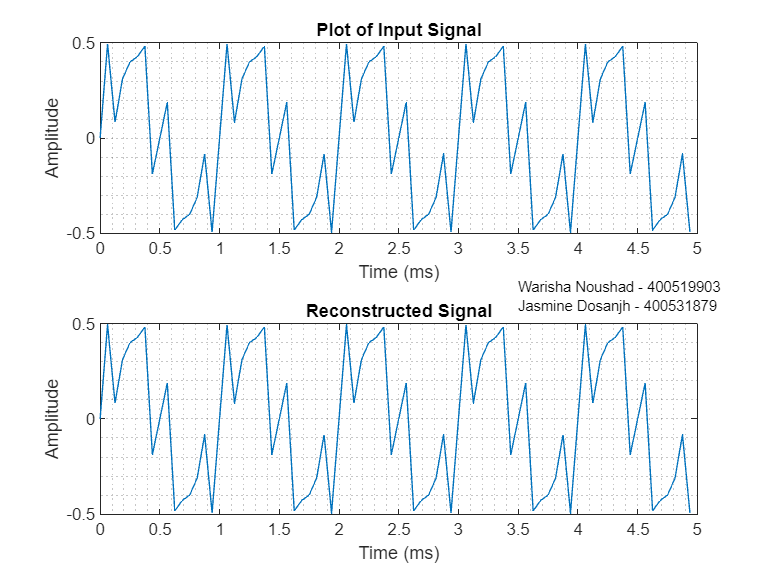

% Read in the signal from the audio file
[signal, Fs] = audioread("tones.wav"); 
L = length(signal);
T = 1/Fs;
t = [0:L-1]*T; 

% Recreate og signal
signal_1 = 0.4*sin(2*pi*1000*t);
signal_2 = 0.2*sin(2*pi*4000*t);
signal_3 = 0.2*sin(2*pi*6000*t);
combinedSignal = signal_1 + signal_2 + signal_3;

% Plot the signal for t_plot msec
t_plot = 5;
msec_per_sec = 1000;
numSamples = t_plot*Fs/msec_per_sec; % takes 5 ms of audio

tiledlayout("vertical")
x = 0:0.1:5;
nexttile;
plot(msec_per_sec*t(1:numSamples), signal(1:numSamples))
title('Plot of Input Signal'); xlabel('Time (ms)'); ylabel('Amplitude'); grid('minor')
nexttile
plot(msec_per_sec*t(1:numSamples), combinedSignal(1:numSamples))
title('Reconstructed Signal'); xlabel('Time (ms)'); ylabel('Amplitude'); grid('minor')

%Export the graph
text(3.5, 0.6, 'Jasmine Dosanjh - 400531879', 'FontSize', 8)
text(3.5, 0.7, 'Warisha Noushad - 400519903', 'FontSize', 8)
exportgraphics(gcf, "P1_Q8.jpg")